## problem 1 

clear all; close all; clc;

### (d)


% Import data as matrix 
Cl_vs_Cd = readtable('p1_c_Cl_vs_Cd.csv');  % Read file 
Cl_vs_Cd = table2array(Cl_vs_Cd);  % convert table to array 
Cl = Cl_vs_Cd(:,2);  % Assign Cl values 
Cd = Cl_vs_Cd(:,1);  % Assign Cd values 
dydx = Cl./Cd;  % Find the gradient of each points 
[max_Cl_over_Cd, idx] = max(dydx)

max_Cl_over_Cd = 105.1151

idx = 112

Cd_idx = Cd(idx)

Cd_idx = 0.0053

Cl_idx = Cl(idx)

Cl_idx = 0.5578

% Tangential line 
x = linspace(0,0.03);
y = Cl_idx/Cd_idx.*x;

% Finding local maximums 
Cl_over_Cd_vs_AoA = csvread('p1_d_Cl_over_Cd_vs_AoA.csv');
Cl_over_Cd = Cl_over_Cd_vs_AoA(:,2);
AoA1 = Cl_over_Cd_vs_AoA(:,1);
local_max_idx = islocalmax(Cl_over_Cd);
local_max_Cl = Cl(local_max_idx);
local_max_Cd = Cd(local_max_idx);
local_max_AoA = AoA1(local_max_idx)

local_max_AoA =   -24.0000
   -9.2500
    3.2500
    8.5000


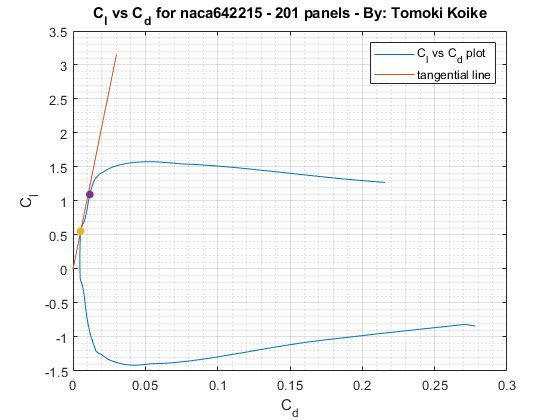


% Plotting
fig1 = figure('Renderer','painters');
plot(Cd, Cl)
title('C_l vs C_d for naca642215 - 201 panels - By: Tomoki Koike')
xlabel('C_d')
ylabel('C_l')
hold on
plot(x,y)
plot(local_max_Cd(3), local_max_Cl(3),'.','MarkerSize',20)
plot(local_max_Cd(4), local_max_Cl(4),'.','MarkerSize',20)
hold off
legend('C_l vs C_d plot', 'tangential line')
grid on
grid minor
box on
saveas(fig1, 'p1_d_tangential_line.png')

#### <h>

[max_Cl, idx2] = max(Cl)

max_Cl = 1.5777

idx2 = 166

AoA_maxCl = AoA1(idx2)

AoA_maxCl = 18.2500

## problem 2


% Import data as matrix 
Cl_vs_Cd_new = readtable('p2_c_Cl_vs_Cd.csv');  % Read file 
Cl_vs_Cd_new = table2array(Cl_vs_Cd_new);  % convert table to array 
Cl3 = Cl_vs_Cd_new(:,2);  % Assign Cl values 
Cd3 = Cl_vs_Cd_new(:,1);  % Assign Cd values 
dydx3 = Cl3./Cd3;  % Find the gradient of each points 
[max_Cl_over_Cd3, idx3] = max(dydx3)

max_Cl_over_Cd3 = 105.1151

idx3 = 112

Cd_idx3 = Cd3(idx3)

Cd_idx3 = 0.0053

Cl_idx3 = Cl3(idx3)

Cl_idx3 = 0.5578

% Tangential line 
x3 = linspace(0,0.03);
y3 = Cl_idx3/Cd_idx3.*x3;

Cl9 = Cl_vs_Cd_new(:,4);  % Assign Cl values 
Cd9 = Cl_vs_Cd_new(:,3);  % Assign Cd values 
dydx9 = Cl9./Cd9;  % Find the gradient of each points 
[max_Cl_over_Cd9, idx9] = max(dydx9)

max_Cl_over_Cd9 = 116.9898

idx9 = 134

Cd_idx9 = Cd9(idx9)

Cd_idx9 = 0.0098

Cl_idx9 = Cl9(idx9)

Cl_idx9 = 1.1484

% Tangential line 
x9 = linspace(0,0.03);
y9 = Cl_idx/Cd_idx.*x3;

% Finding local maximums 
% 3M
Cl_over_Cd_vs_AoA_new = csvread('Polar_Graph_4.csv');
Cl_over_Cd3 = Cl_over_Cd_vs_AoA_new(:,2);
AoA3 = Cl_over_Cd_vs_AoA_new(:,1);
local_max_idx3 = islocalmax(Cl_over_Cd3)

local_max_idx3 = 198×1 logical array
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0


local_max_Cl3 = Cl3(local_max_idx3)

local_max_Cl3 =    -0.8140
   -0.8552
    0.5578
    1.0953


local_max_Cd3 = Cd3(local_max_idx3)

local_max_Cd3 =     0.2711
    0.0109
    0.0053
    0.0116


local_max_AoA3 = AoA3(local_max_idx3)

local_max_AoA3 =   -24.0000
   -9.2500
    3.2500
    8.5000


% 9M
Cl_over_Cd9 = Cl_over_Cd_vs_AoA_new(:,4);
AoA9 = Cl_over_Cd_vs_AoA_new(:,3);
local_max_idx9 = islocalmax(Cl_over_Cd9)

local_max_idx9 = 198×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


local_max_Cl9 = Cl9(local_max_idx9)

local_max_Cl9 =     0.4155
    0.5513
    1.1484
    1.2245


local_max_Cd9 = Cd9(local_max_idx9)

local_max_Cd9 =     0.0044
    0.0058
    0.0098
    0.0105


local_max_AoA9 = AoA9(local_max_idx9)

local_max_AoA9 =     2.0000
    3.2500
    8.7500
    9.5000


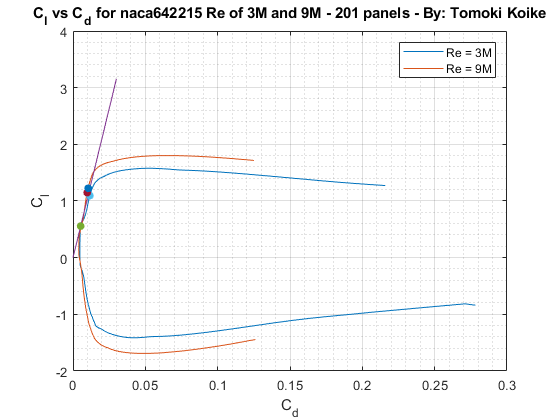


% Plotting
fig2 = figure('Renderer','painters');
plot(Cd3, Cl3)
title('C_l vs C_d for naca642215 Re of 3M and 9M - 201 panels - By: Tomoki Koike')
xlabel('C_d')
ylabel('C_l')
hold on
plot(Cd9,Cl9)
plot(x9,y9)
plot(x3,y3)
plot(local_max_Cd3(3), local_max_Cl3(3),'.','MarkerSize',20)
plot(local_max_Cd3(4), local_max_Cl3(4),'.','MarkerSize',20)
plot(local_max_Cd9(3), local_max_Cl9(3),'.','MarkerSize',20)
plot(local_max_Cd9(4), local_max_Cl9(4),'.','MarkerSize',20)
hold off
legend('Re = 3M', 'Re = 9M')
grid on
grid minor
box on
saveas(fig2, 'p2_d_tangential_line.png')

[max_Cl9, idx_oho] = max(Cl9)

max_Cl9 = 1.8018

idx_oho = 185

AoA_maxCl9999 = AoA9(idx_oho)

AoA_maxCl9999 = 21.7500